## Load saved connectivity data

Contains a table of hemibrain connectivity data for LH-DANs and a variety of other comparison cells.

parentDir = 'C:\Users\Wilson Lab\Google Drive\Lab Work\LH-DAN_connectomics_analysis';
tbl = readtable(fullfile(parentDir, 'full_connectivity_table_all_cells.csv'), ...
    'delimiter', ',');

## Set initial analysis parameters

p = [];
p.dropPPL105 = 1;    % Drops the bilateral neurons that are incomplete in the Hemibrain volume
p.combinePPL105 = 0; % Combines the PPL105 neurons from the left and right hemispheres
p.partnerDirection = 'upstream'; % 'downstream'; %
p.yVarType = 'percentage'; % 'count'; %
p.yScaleType = 'log'; % 'log'; %
p.xNorm = 1;
p.xMinPct = 90;
p.groupPartnersByType = 1;
p.tracedPartnersOnly = 1;
p.summaryTableRows = 15;
p.legendPos = 'nw';
p.saveFig = 0;
p.figDims = [];

% p.cm = jet(size((currTypeList), 1)) * 0.95;

p.cellTypeClasses = [1 1 2 2 2 3 3 3 4 4 4 5 5 6 6 6 6 7 7 7];
p.cellTypeClassNames = {'AL-PN', 'E-PG', 'LH-ON', 'PAM-DAN', 'PFL1', 'LH-DAN', 'AL-LN'};

p.cm = [rgb('blue'); rgb('cyan'); rgb('red'); rgb('green'); rgb('magenta'); rgb('orange'); rgb('brown')];

% p.cm = [rgb('blue'); rgb('blue'); ...
%     rgb('cyan'); rgb('cyan'); rgb('cyan'); ...
%     rgb('red'); rgb('red'); rgb('red'); ...
%     rgb('green'); rgb('green'); rgb('green'); ...
%     rgb('magenta'); rgb('magenta'); ...
%     %         rgb('black'); ...
%     rgb('orange'); rgb('orange'); rgb('orange'); rgb('orange'); ...
%     rgb('brown'); rgb('brown'); rgb('brown'); rgb('brown')];

## Make scatter plots of summary variables

p.figDims = [920 760];

#### Upstream

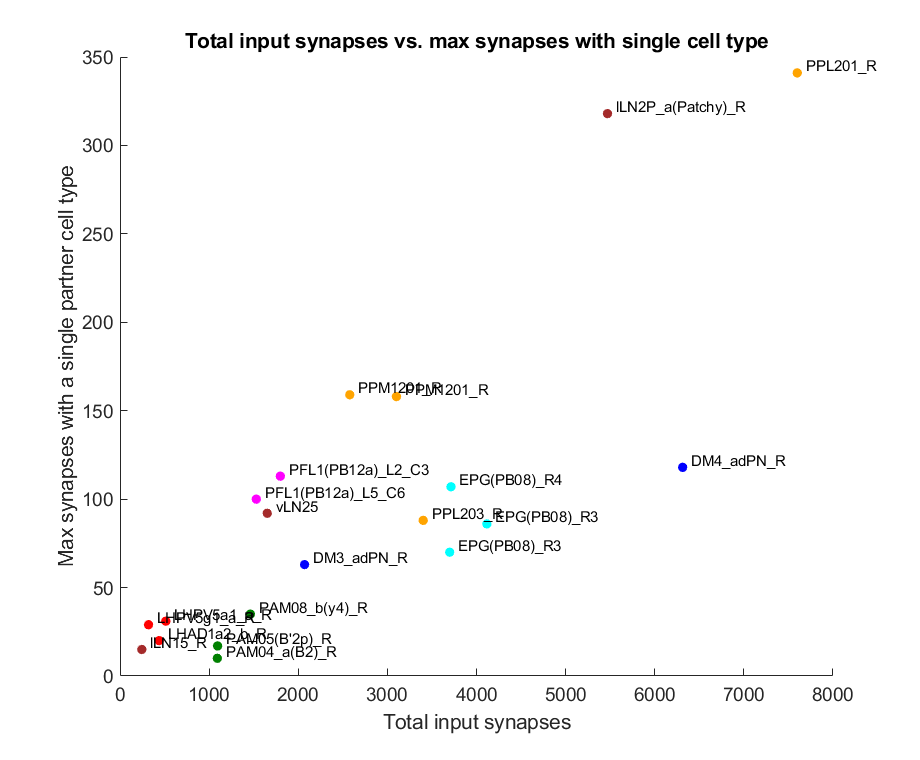

p.partnerDirection = 'upstream';
[~, ~, neuronList, totalSynapseCounts, ~, partnerTypeCounts, directionStr, maxSynapseCounts] = ...
        preprocess_data(tbl, p);
[f_up, g_up, fName_f_up, fName_g_up] = make_scatter_plots(neuronList, totalSynapseCounts, p, ...
        partnerTypeCounts, directionStr, maxSynapseCounts);
f_up.Children.Title.String = capitalize(regexprep(fName_f_up, {'\_', 'vs'}, {' ', 'vs.'}));

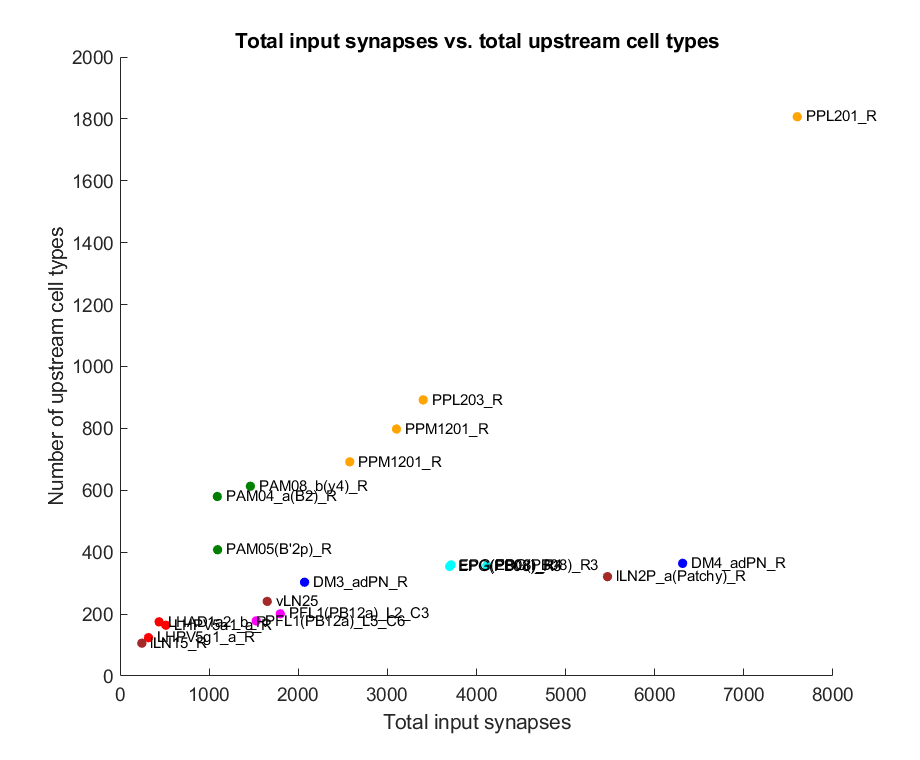

g_up.Children.Title.String = capitalize(regexprep(fName_g_up, {'\_', 'vs'}, {' ', 'vs.'}));

#### Downstream

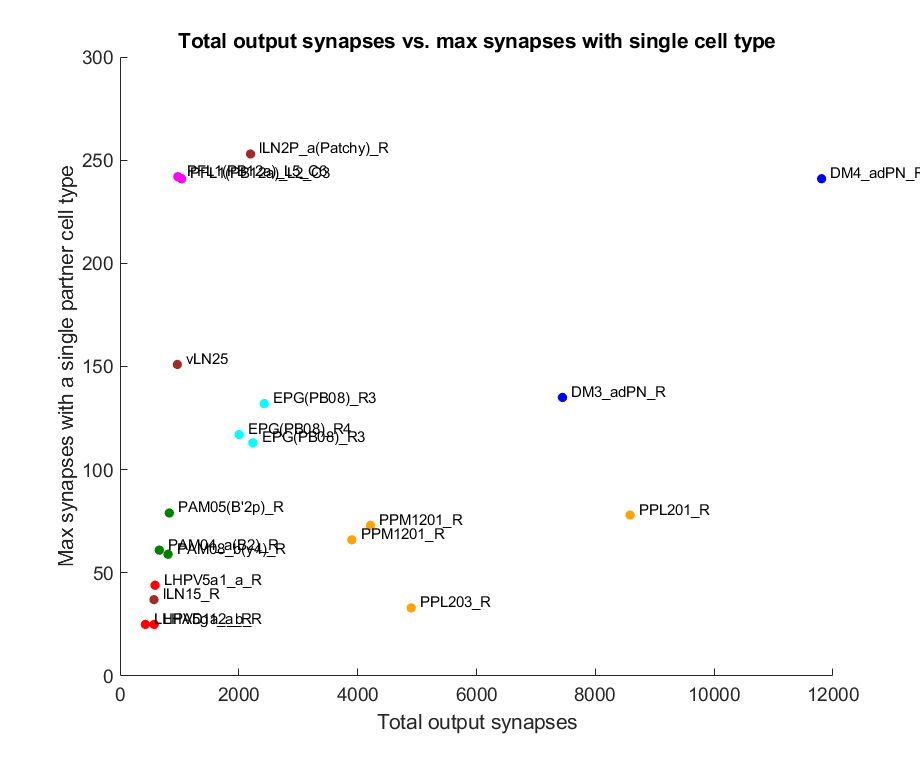

p.partnerDirection = 'downstream';
[~, ~, neuronList, totalSynapseCounts, ~, partnerTypeCounts, directionStr, maxSynapseCounts] = ...
        preprocess_data(tbl, p);
[f_down, g_down, fName_f_down, fName_g_down] = make_scatter_plots(neuronList, totalSynapseCounts, p, ...
        partnerTypeCounts, directionStr, maxSynapseCounts);
f_down.Children.Title.String = capitalize(regexprep(fName_f_down, {'\_', 'vs'}, {' ', 'vs.'}));

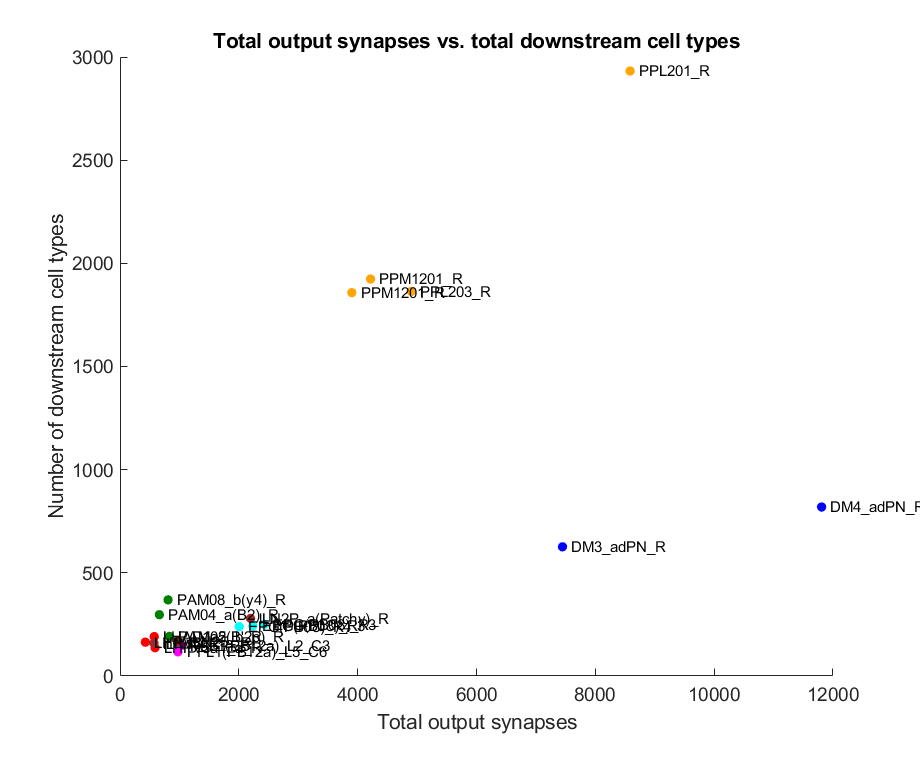

g_down.Children.Title.String = capitalize(regexprep(fName_g_down, {'\_', 'vs'}, {' ', 'vs.'}));

## Plot sorted partner count line plots

p.figDims = [960 870];

#### Upstream, linear Y-scale

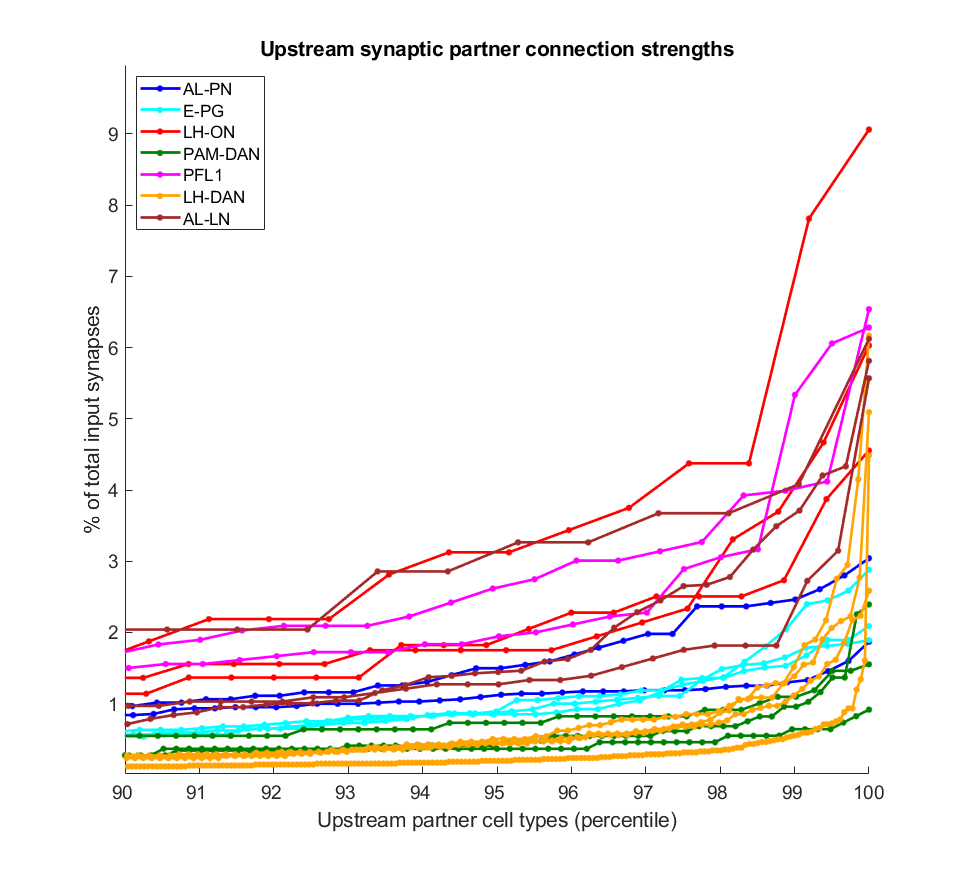

p.partnerDirection = 'upstream';
p.yScaleType = 'linear';
[overallMinVal, partnerTypeTbl, neuronList, ~, overallMaxVal, ~, directionStr, ~] = preprocess_data(tbl, p);
f_up_lin = make_line_plot(overallMinVal, partnerTypeTbl, neuronList, overallMaxVal, p, directionStr);

#### Upstream, log Y-scale

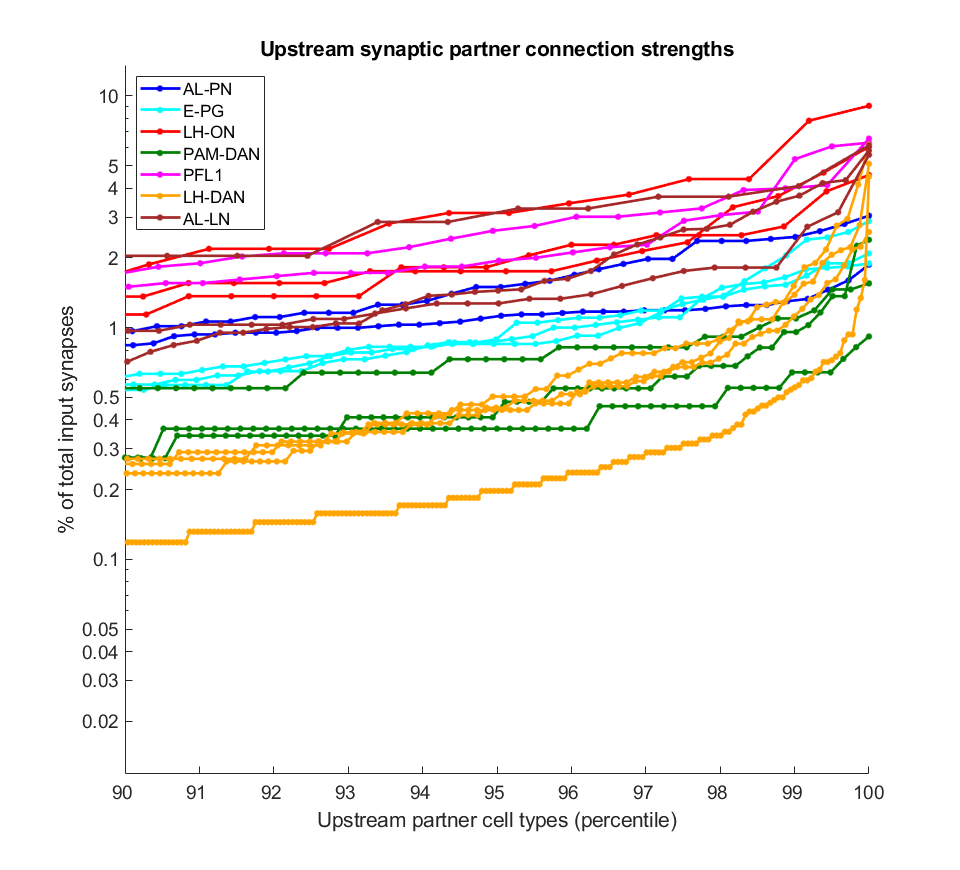

p.partnerDirection = 'upstream';
p.yScaleType = 'log';
[overallMinVal, partnerTypeTbl, neuronList, ~, overallMaxVal, ~, directionStr, ~] = preprocess_data(tbl, p);
f_up_log = make_line_plot(overallMinVal, partnerTypeTbl, neuronList, overallMaxVal, p, directionStr);

#### Downstream, linear Y-scale

outputTbl = [];
for iType = 1:size(neuronList, 1)
    currData = partnerTypeTbl(strcmp(partnerTypeTbl.neuronID, neuronList.neuronID{iType}), :);
    currData = sortrows(currData, 'synapseCount', 'descend');
    
    nPartners = size(currData, 1);
    pctCutoffInd = round(nPartners * .1);
%     pctCutoffInd = 10;

    topPartnerTotalPct = cumsum(currData.connectionWeightPct(1:pctCutoffInd));
    cumPctVal = topPartnerTotalPct(end);
    cutoffPartnerVal = currData.connectionWeightPct(pctCutoffInd);
    
    topPartnerMeanPct = mean(currData.connectionWeightPct(1:pctCutoffInd));
    
    
    
    outputTbl = [outputTbl; table(neuronList.neuronID(iType), neuronList.neuronName(iType), ...
            cumPctVal, topPartnerMeanPct, cutoffPartnerVal, 'variableNames', {'neuronID', ...
            'neuronName', 'topPartnerCumPct', 'topPartnerMeanPct', 'cutoffPercentile'})];
        
        
end
outputTbl = sortrows(outputTbl, 5)

#### Downstream, log Y-scale

% p.partnerDirection = 'downstream';
% p.yScaleType = 'log';
% [overallMinVal, partnerTypeTbl, neuronList, ~, overallMaxVal, ~, directionStr, ~] = preprocess_data(tbl, p);
% f_down_log = make_line_plot(overallMinVal, partnerTypeTbl, neuronList, overallMaxVal, p, directionStr);

## Export all figures

saveDir = ['C:\Users\Wilson Lab\Documents\MATLAB\2P_code\GroupedAnalysisCode\', ...
            'Manuscript_figure_drafts\Synaptic_partner_distribution'];

% Scatter plots
save_figure(f_up, saveDir, fName_f_up);

save_figure(f_down, saveDir, fName_f_down);

save_figure(g_up, saveDir, fName_g_up);
save_figure(g_down, saveDir, fName_g_down);


% Line plots
save_figure(f_up_lin, saveDir, 'synaptic_partner_connection_strengths_upstream_linearY');

save_figure(f_up_log, saveDir, 'synaptic_partner_connection_strengths_upstream_logY');

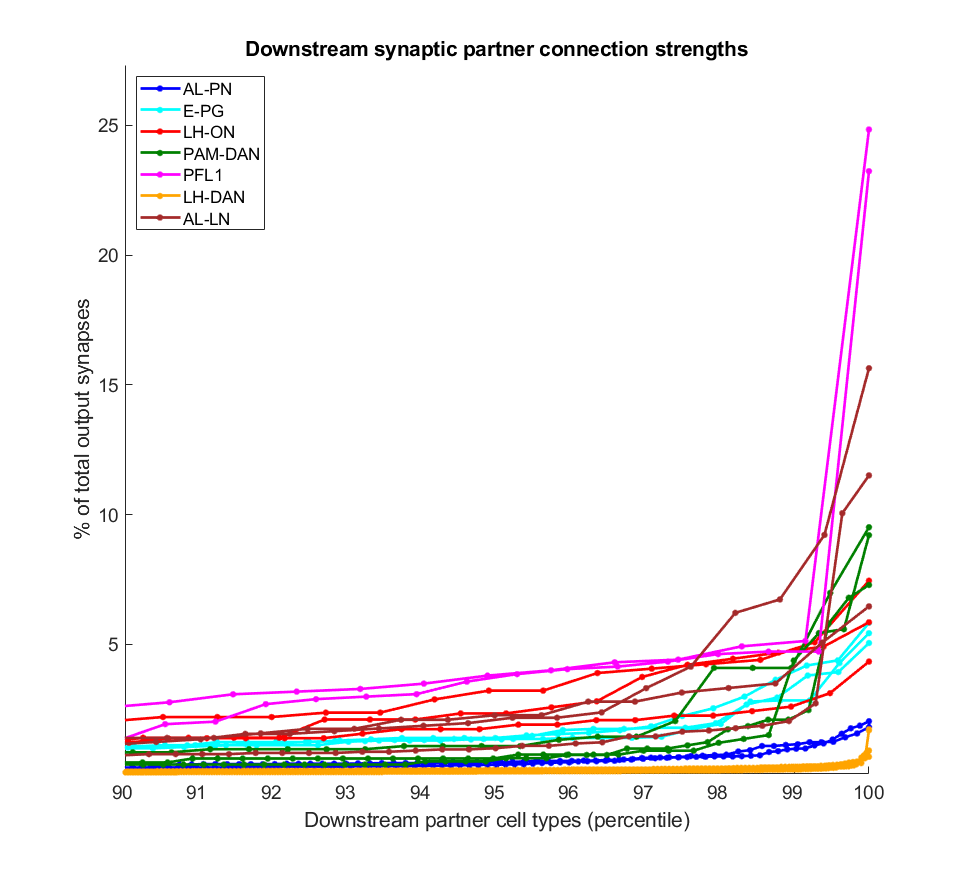

save_figure(f_down_lin, saveDir, 'synaptic_partner_connection_strengths_downstream_linearY');

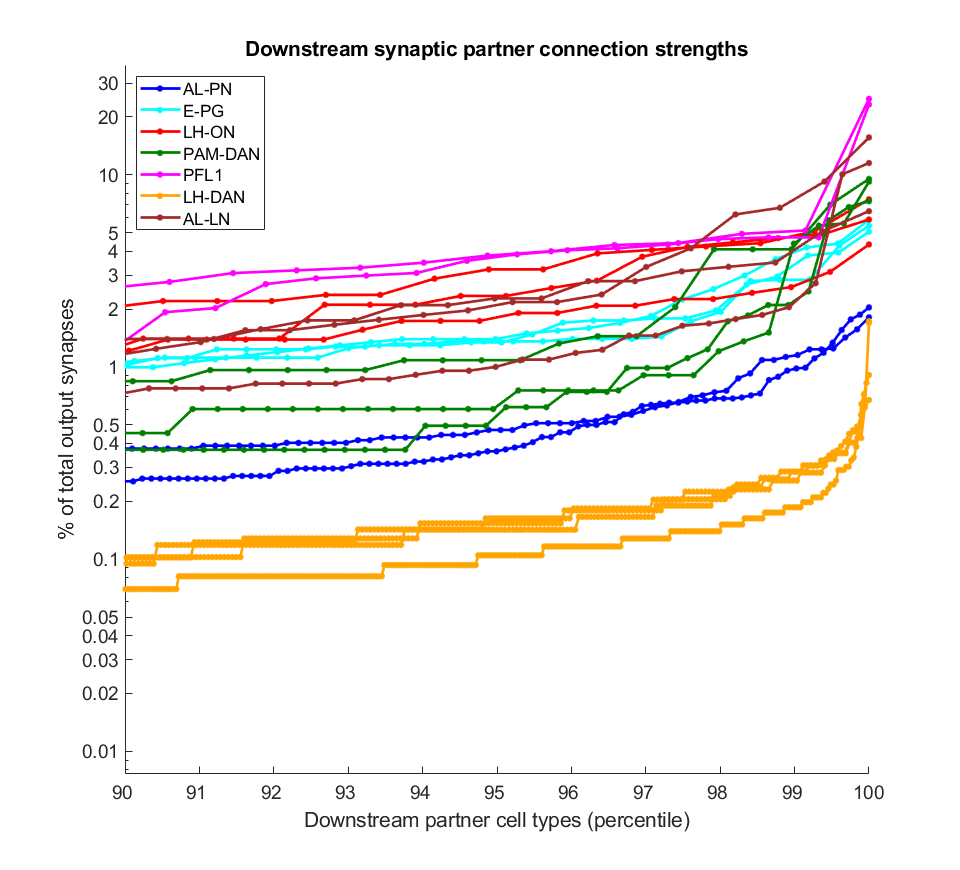

save_figure(f_down_log, saveDir, 'synaptic_partner_connection_strengths_downstream_logY');

## Local functions

function ax = logify(ax, yExpLims)

% Change Y axis to a log scale and set tick labels
YTickVals = [];
baseYTickVals = [10^yExpLims(1):10^yExpLims(1):(10^yExpLims(1) * 5)];
for i = 1:diff(yExpLims)
    YTickVals = [YTickVals, baseYTickVals * 10^(i-1)];
end
YTickVals(end + 1) = 10^yExpLims(2);
ax.YScale = 'log';
ax.YTick = YTickVals;

end

% --------------------------------------------------------------------------------------------------------
% Preprocess data based on current settings
% --------------------------------------------------------------------------------------------------------
function [overallMinVal, partnerTypeTbl, neuronList, totalSynapseCounts, overallMaxVal, ...
            partnerTypeCounts, directionStr, maxSynapseCounts] = preprocess_data(tbl, p)
        
% Drop rows for partners that are incompletely traced or too small
if p.tracedPartnersOnly
    tbl = tbl(strcmpi(tbl.partnerStatus, 'traced') & tbl.partnerSize > 1.2e8, :);
end

% Create data table
dt = DataTable(tbl);
filterDefs = struct();
filterDefs.partnerDirection = p.partnerDirection;
filterDefs.partnerDirection = p.partnerDirection;
if strcmp(filterDefs.partnerDirection, 'downstream')
    directionStr = 'output';
else
    directionStr = 'input';
end

% Adjust PPL105 if necessary
if p.dropPPL105
    dt.sourceData = dt.sourceData(~strcmp(dt.sourceData.neuronType, 'PPL105'), :);
elseif p.combinePPL105
    dt.sourceData(strcmp(dt.sourceData.neuronID, '642516892'), 'neuronID') = {'5813019513'};
    dt.sourceData(strcmp(dt.sourceData.neuronName, 'PPL105(a''2a2)(PDL05)_L'), 'neuronName') = ...
        {'PPL105(a''2a2)_R'};
end

% Get lists of unique neurons and cell types
neuronList = sortrows(unique(dt.sourceData(:, {'neuronID', 'neuronName'})), 2);

% Initialize loop variables
partnerTypeSummaryTbl = [];
partnerTypeTbl = [];
partnerTypeCounts = [];
maxSynapseCounts = [];
totalSynapseCounts = [];
overallMinVal = inf;
overallMaxVal = 0;
count = 1;

for iType = 1:size(neuronList, 1)
    
    % Get data subset for current neuron
    filterDefs.neuronID = neuronList.neuronID{iType};
    dt = dt.initialize_filters(filterDefs);
    sub = dt.subset;
    
    % Calculate connection weight with each partner as a percentage of total synapses
    totalSynapses = sum(sub.synapseCount);
    connectionWeightPct = 100 * (sub.synapseCount ./ totalSynapses);
    sub.connectionWeightPct = connectionWeightPct;
    
    % Assign a placeholder cell type to each cell that doesn't have one
    for iPartner = 1:size(sub, 1)
        if strcmp(sub.partnerType{iPartner}, 'NA')
            sub.partnerType{iPartner} = ['unknown_', pad(num2str(count), 4, 'left', '0')];
            count = count + 1;
        end
    end
    
    if p.groupPartnersByType
        
        % Create another table that groups partners by cell type
        groupedSub = groupsummary(sub, {'neuronID', 'neuronName', 'partnerDirection', 'partnerID', ...
            'partnerType'}, ...
            'sum', {'synapseCount'});
        groupedSub.connectionWeightPct = 100 * (groupedSub.sum_synapseCount ./ totalSynapses);
        
        % Calculate group counts
        totalSynapseCounts(iType) = sum(groupedSub.sum_synapseCount);
        partnerTypeCounts(iType) = numel(groupedSub.sum_synapseCount);
        maxSynapseCounts(iType) = max(groupedSub.sum_synapseCount);
        
        % Create summary table of top partner cell types
        cellTypeTbl = tail(sortrows(groupedSub, 'connectionWeightPct'), p.summaryTableRows);
        cellTypeTbl.Properties.VariableNames{strcmp(cellTypeTbl.Properties.VariableNames, ...
            'sum_synapseCount')} = 'synapseCount';
        cellTypeTbl.Properties.VariableNames{strcmp(cellTypeTbl.Properties.VariableNames, ...
            'GroupCount')} = 'nCells';
        
        % Add to full table for all cell types
        partnerTypeTbl = [partnerTypeTbl; groupedSub];
        partnerTypeSummaryTbl = [partnerTypeSummaryTbl; cellTypeTbl];
        
        
    else
        % Create summary table of top partner neurons
        singleCellTbl = tail(sortrows(sub(:, {'neuronID', 'neuronName', 'partnerName', 'partnerType', ...
            'partnerDirection', 'synapseCount', 'connectionWeightPct'}), 'connectionWeightPct'), ...
            nRows);
        partnerTypeSummaryTbl = [partnerTypeSummaryTbl; singleCellTbl];
    end
    
end

% Rename sum_synapseCount column in partnerTypeTbl if necessary
if p.groupPartnersByType
    partnerTypeTbl.Properties.VariableNames{strcmp(partnerTypeTbl.Properties.VariableNames, ...
        'sum_synapseCount')} = 'synapseCount';
    partnerTypeTbl.Properties.VariableNames{strcmp(partnerTypeTbl.Properties.VariableNames, ...
        'GroupCount')} = 'nCells';
end
end

% --------------------------------------------------------------------------------------------------------
% Generate scatterplot 
% --------------------------------------------------------------------------------------------------------
function [f, g, fileName_f, fileName_g] = make_scatter_plots(neuronList, totalSynapseCounts, p, ...
            partnerTypeCounts, directionStr, maxSynapseCounts)
    
    % Prepare plotting data
    tb = table(neuronList.neuronName, totalSynapseCounts', partnerTypeCounts', maxSynapseCounts', ...
        'variablenames', {'cellType', 'totalSynapses', 'totalPartnerTypes', 'maxSynapseCount'});
    xx = tb.totalSynapses;
    yy = tb.maxSynapseCount;
    xLab = ['Total ', directionStr, ' synapses'];
    dx = ones(size(xx)) * (max(xx) * 0.0125);
    dy = ones(size(xx)) * (max(yy) * 0.0125);
    
    % Create figure for "total partner cell types" plot
    yLab = ['Max synapses with a single partner cell type'];
    fileName_f = ['total_', directionStr, '_synapses_vs_max_synapses_with_single_cell_type'];
    
    f = figure;clf;
    f.Color = [1 1 1];
    if ~isempty(p.figDims)
        f.Position(3:4) = p.figDims;
    end
    f.UserData.plotParams = p;
    f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
    ax = axes(); hold on; 
    scatter(xx, yy, 50, p.cm(p.cellTypeClasses, :), 'filled')
%     plot(xx, yy, '.', 'color', 'b', 'markersize', 25);
    ax = gca();
    ax.FontSize = 14;
    xlabel(xLab)
    ylabel(yLab)
    c = regexprep(tb.cellType, '_', '\\_');
    text(xx + dx, yy + dy, c, 'FontSize', 11);
    
    % Create figure for "max synapses with single partner type" plot
    yy = tb.totalPartnerTypes;
    yLab = ['Number of ', p.partnerDirection, ' cell types'];
    fileName_g = ['total_', directionStr, '_synapses_vs_total_', p.partnerDirection, '_cell_types'];
    g = figure; clf;
    g.Color = [1 1 1];
    if ~isempty(p.figDims)
        g.Position(3:4) = p.figDims;
    end
    g.UserData.plotParams = p;
    g.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
    ax = axes(); hold on;
    scatter(xx, yy, 50, p.cm(p.cellTypeClasses, :), 'filled')
%     plot(xx, yy, '.', 'color', 'b', 'markersize', 25);
    ax = gca();
    ax.FontSize = 14;
    xlabel(xLab)
    ylabel(yLab)
    c = regexprep(tb.cellType, '_', '\\_');
    text(xx + dx, yy + dy, c, 'FontSize', 11);
end

% --------------------------------------------------------------------------------------------------------
% Generate line plots 
% --------------------------------------------------------------------------------------------------------
function f = make_line_plot(overallMinVal, partnerTypeTbl, neuronList, overallMaxVal, p, directionStr)

    % Create figure
    f = figure;clf;
    f.Color = [1 1 1];
    if ~isempty(p.figDims)
        f.Position(3:4) = p.figDims;
    end
    f.UserData.plotParams = p;
    f.UserData.gitInfo = getGitInfo('C:\Users\Wilson Lab\Documents\MATLAB\2P_code');
    ax = axes(); hold on;
    
    for iType = 1:size((neuronList), 1)
        
        currData = partnerTypeTbl(strcmp(partnerTypeTbl.neuronID, neuronList.neuronID{iType}), :);
        
        plotCm = p.cm(p.cellTypeClasses, :);
        
        % Get correct plot data for selected options
        pctData = currData.connectionWeightPct;
        countData = currData.synapseCount;
        if strcmpi(p.yVarType, 'count')
            yy = sort(countData);
        else
            yy = sort(pctData);
            %         yy = cumsum(sort(pctData));
        end
        if p.xNorm
            xx = (1:numel(yy)) ./ numel(yy);
        else
            xx = 1:numel(yy);
        end
        
        % Keep track of overall min and max vals for setting final axes limits
        overallMinVal = min(overallMinVal, min(yy));
        overallMaxVal = max(overallMaxVal, max(yy));
        
        % Plot data
        plot(ax, xx, yy, '-', 'linewidth', 2, 'color', plotCm(iType, :));
        ax.Children(1).Marker = '.';
        ax.Children(1).MarkerSize = 15;
        ax.FontSize = 14;
        if iType == 1
            lineObjects = ax.Children;
        else
            lineObjects(end + 1) = ax.Children(1);
        end
        
        % Change Y-axis to a log scale if necessary
        if strcmp(p.yScaleType, 'log')
            ax = logify(ax, [log10(exp_floor(overallMinVal)), log10(exp_ceil(overallMaxVal))]);
        end
        
        % Set Y limits
        if strcmp(p.yScaleType, 'log')
            ax.YLim = [overallMinVal, overallMaxVal] .* [0.9, 1.5];
        else
            ax.YLim = [overallMinVal, overallMaxVal] .* [0.9, 1.1];
        end
        
        % Set X limits if necessary
        if p.xNorm
            xlim(ax, [p.xMinPct/100, 1]);
            %     ax.XTickLabels = '';
        elseif p.xMinPct > 0
            xL = xlim();
            pctThresh = round(xL(2) * (p.xMinPct / 100));
            xlim([pctThresh, xL(2)])
        end
        
        ax.XTickLabel = ax.XTick * 100;
        ax.XTickLabelMode = 'manual';
        ax.XTickMode = 'manual';
        
        % Add legend and labels
        if strcmp(p.yVarType, 'count')
            ylabel('Synapse count');
        else
            ylabel(['% of total ', directionStr, ' synapses']);
        end
        if p.groupPartnersByType
            xlabel([capitalize(p.partnerDirection), ' partner cell types'])
        else
            xlabel([capitalize(p.partnerDirection), ' partner cells'])
        end
        if p.xNorm
            ax.XLabel.String = [ax.XLabel.String, ' (percentile)'];
        end
        
        %lg = legend(lineObjects(), regexprep(neuronList.neuronName, '_', '\\_'), ...
        %   'location', p.legendPos);
        
    end
    title([capitalize(p.partnerDirection), ' synaptic partner connection strengths'])
    [~, legendObjectInds, ~] = unique(p.cellTypeClasses);
    lg = legend(lineObjects(legendObjectInds), p.cellTypeClassNames, 'location', p.legendPos);
end